# Build AircraftData Struct


clear variables; close all; clc;


## Aircraft data

### Aircraft (reference, turbo-prop)

% ATR-42-600
AircraftData.Name = "Regional transport turbo-prop";
AircraftData.mass_0 = 18600;                 % Initial mass (kg)
AircraftData.W_0 = AircraftData.mass_0*9.81; % Initial weight (N)
AircraftData.S = 54.56;                      % Wing area (m^2)
AircraftData.b_wing = 24.57;                 % Wingspan (m)
AircraftData.AR = ...                        % Aspect ratio 
    AircraftData.b_wing^2 ...
    / AircraftData.S;

AircraftData.Propulsion.eta_p = 0.85;                  % Shaft efficiency
AircraftData.Propulsion.PI_shaft_0 = 2*2050000;        % Maximum shaft power at take-off (2 engines) (W)
AircraftData.Propulsion.PI_avail_0 = ...               % Maximum available power at take-off (W)
    AircraftData.Propulsion.PI_shaft_0 ...
    * AircraftData.Propulsion.eta_p;

From the manufacturer

T0 = 2 * 6860 lbf

PI0 = 2 * 2450 hp

### Lift coefficient in TAKE-OFF configuration (linear an nonlinear parts, function of AoA)

% Parameters

AircraftData.Aerodynamics.CL_0_TO = 0.90;              % A/C lift coeff. at 0 AoA, Take-off (has flaps)
AircraftData.Aerodynamics.CL_max_TO = 2.17;            % A/C max lift coeff.
AircraftData.Aerodynamics.alpha_stall_deg_TO = 15.0;   % Stall AoA (deg)
AircraftData.Aerodynamics.alpha_star_deg_TO = 9.0;     % End of CL-linearity AoA (deg)
AircraftData.Aerodynamics.CL_alpha_TO = 5.9;           % A/C lift curve slope (1/rad)

AircraftData.Aerodynamics.delta_flap_deg_TO = 15.0;

% Linear part, 1
AircraftData.Aerodynamics.Interp.alpha_min_deg = -12.0;
AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1 = convang( ...
    [AircraftData.Aerodynamics.Interp.alpha_min_deg, 0, AircraftData.Aerodynamics.alpha_star_deg_TO], 'deg', 'rad');
AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1 = [
    AircraftData.Aerodynamics.CL_0_TO + AircraftData.Aerodynamics.CL_alpha_TO*AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1(1), ...
        AircraftData.Aerodynamics.CL_0_TO, ...
            AircraftData.Aerodynamics.CL_0_TO + AircraftData.Aerodynamics.CL_alpha_TO*AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1(3)];

AircraftData.Aerodynamics.Interp.f_CL_TO_1 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1, AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1, alpha);

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_TO_1 = linspace(AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1(1), AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_TO_1 = AircraftData.Aerodynamics.Interp.f_CL_TO_1(AircraftData.Aerodynamics.Interp.v_AoA_TO_1);

% Nonlinear part
AircraftData.Aerodynamics.Interp.alpha_max_deg = AircraftData.Aerodynamics.alpha_stall_deg_TO + 8.0;
AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2 = convang( ...
    [AircraftData.Aerodynamics.alpha_star_deg_TO, ...
        AircraftData.Aerodynamics.alpha_star_deg_TO + 0.5, ...
            AircraftData.Aerodynamics.alpha_stall_deg_TO, ...
                AircraftData.Aerodynamics.alpha_stall_deg_TO ...
                    + 0.5*(AircraftData.Aerodynamics.Interp.alpha_max_deg - AircraftData.Aerodynamics.alpha_stall_deg_TO), ...
                    AircraftData.Aerodynamics.Interp.alpha_max_deg],'deg','rad');
AircraftData.Aerodynamics.Interp.v_CL_TO_bp_2 = [ ...
    AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1(end), ...
        AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1(end) ...
            + AircraftData.Aerodynamics.CL_alpha_TO*(AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2(2) - AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2(1)), ...
            AircraftData.Aerodynamics.CL_max_TO, ...
                0.85*AircraftData.Aerodynamics.CL_max_TO, ...
                    0.75*AircraftData.Aerodynamics.CL_max_TO];

AircraftData.Aerodynamics.Interp.f_CL_TO_2 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2, AircraftData.Aerodynamics.Interp.v_CL_TO_bp_2, alpha,"pchip");

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_TO_2 = linspace( ...
    AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2(1), AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_TO_2 = AircraftData.Aerodynamics.Interp.f_CL_TO_2(AircraftData.Aerodynamics.Interp.v_AoA_TO_2);

### Lift coefficient in CLEAN configuration (linear an nonlinear parts, function of AoA)

AircraftData.Aerodynamics.CL_alpha_CLEAN = 5.9;
AircraftData.Aerodynamics.CL_0_CLEAN = 0.3;
AircraftData.Aerodynamics.CL_max_CLEAN = 1.7;
AircraftData.Aerodynamics.alpha_stall_deg_CLEAN = 16.0;
AircraftData.Aerodynamics.alpha_star_deg_CLEAN = 9.5;

AircraftData.Aerodynamics.delta_flap_deg_CLEAN = 0.0;

% Linear part, 1
%alpha_min_deg = -5.0;
AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1 = convang( ...
    [AircraftData.Aerodynamics.Interp.alpha_min_deg, 0, AircraftData.Aerodynamics.alpha_star_deg_CLEAN], 'deg', 'rad');
AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1 = [ ...
    AircraftData.Aerodynamics.CL_0_CLEAN + AircraftData.Aerodynamics.CL_alpha_CLEAN*AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1(1), ...
    AircraftData.Aerodynamics.CL_0_CLEAN, ...
    AircraftData.Aerodynamics.CL_0_CLEAN + AircraftData.Aerodynamics.CL_alpha_CLEAN*AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1(3)];

AircraftData.Aerodynamics.Interp.f_CL_CLEAN_1 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1, AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1, alpha);

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_1 = linspace( ...
    AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1(1), AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_CLEAN_1 = AircraftData.Aerodynamics.Interp.f_CL_CLEAN_1(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_1);

% Nonlinear part
%alpha_max_deg = alpha_stall_deg_TO + 8.0;
AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2 = convang( ...
    [AircraftData.Aerodynamics.alpha_star_deg_CLEAN, ...
        AircraftData.Aerodynamics.alpha_star_deg_CLEAN + 0.5, ...
            AircraftData.Aerodynamics.alpha_stall_deg_CLEAN, ...
                AircraftData.Aerodynamics.alpha_stall_deg_CLEAN ...
                    + 0.5*(AircraftData.Aerodynamics.Interp.alpha_max_deg - AircraftData.Aerodynamics.alpha_stall_deg_CLEAN), ...
                    AircraftData.Aerodynamics.Interp.alpha_max_deg],'deg','rad');
AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_2 = [ ...
    AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1(end), ...
        AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1(end) ...
        + AircraftData.Aerodynamics.CL_alpha_CLEAN*(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2(2) - AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2(1)), ...
            AircraftData.Aerodynamics.CL_max_CLEAN, ...
                0.85*AircraftData.Aerodynamics.CL_max_CLEAN, ...
                    0.75*AircraftData.Aerodynamics.CL_max_CLEAN];

AircraftData.Aerodynamics.Interp.f_CL_CLEAN_2 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2, AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_2, alpha,"pchip");

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_2 = linspace( ...
    AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2(1), AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_CLEAN_2 = AircraftData.Aerodynamics.Interp.f_CL_CLEAN_2(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_2);

### Lift coefficient in LANDING configuration (linear an nonlinear parts, function of AoA)

AircraftData.Aerodynamics.CL_alpha_LND = 6.0;
AircraftData.Aerodynamics.CL_0_LND = 1.22;
AircraftData.Aerodynamics.CL_max_LND = 2.6;
AircraftData.Aerodynamics.alpha_stall_deg_LND = 14.5;
AircraftData.Aerodynamics.alpha_star_deg_LND = 8.0;

AircraftData.Aerodynamics.delta_flap_deg_LND = 30.0;

% Linear part, 1
%alpha_min_deg = -5.0;
AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1 = convang( ...
    [AircraftData.Aerodynamics.Interp.alpha_min_deg, 0, AircraftData.Aerodynamics.alpha_star_deg_LND], 'deg', 'rad');
AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1 = [ ...
    AircraftData.Aerodynamics.CL_0_LND ...
        + AircraftData.Aerodynamics.CL_alpha_LND*AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1(1), ...
    AircraftData.Aerodynamics.CL_0_LND, ...
    AircraftData.Aerodynamics.CL_0_LND ...
        + AircraftData.Aerodynamics.CL_alpha_LND*AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1(3)];

AircraftData.Aerodynamics.Interp.f_CL_LND_1 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1, AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1, alpha);

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_LND_1 = linspace( ...
    AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1(1), AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_LND_1 = AircraftData.Aerodynamics.Interp.f_CL_LND_1(AircraftData.Aerodynamics.Interp.v_AoA_LND_1);

% Nonlinear part
%alpha_max_deg = alpha_stall_deg_TO + 8.0;
AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2 = convang( ...
    [AircraftData.Aerodynamics.alpha_star_deg_LND, ...
        AircraftData.Aerodynamics.alpha_star_deg_LND + 0.5, ...
            AircraftData.Aerodynamics.alpha_stall_deg_LND, ...
                AircraftData.Aerodynamics.alpha_stall_deg_LND ...
                + 0.5*(AircraftData.Aerodynamics.Interp.alpha_max_deg - AircraftData.Aerodynamics.alpha_stall_deg_LND), ...
                    AircraftData.Aerodynamics.Interp.alpha_max_deg],'deg','rad');
AircraftData.Aerodynamics.Interp.v_CL_LND_bp_2 = [ ...
    AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1(end), ...
        AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1(end) ...
        + AircraftData.Aerodynamics.CL_alpha_LND*(AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2(2) - AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2(1)), ...
            AircraftData.Aerodynamics.CL_max_LND, ...
                0.85*AircraftData.Aerodynamics.CL_max_LND, ...
                    0.75*AircraftData.Aerodynamics.CL_max_LND];

AircraftData.Aerodynamics.Interp.f_CL_LND_2 = @(alpha) ...
    interp1(AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2, AircraftData.Aerodynamics.Interp.v_CL_LND_bp_2, alpha,"pchip");

% discrete values, just used in plots
AircraftData.Aerodynamics.Interp.v_AoA_LND_2 = linspace( ...
    AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2(1), AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2(end), 20);
AircraftData.Aerodynamics.Interp.v_CL_LND_2 = AircraftData.Aerodynamics.Interp.f_CL_LND_2(AircraftData.Aerodynamics.Interp.v_AoA_LND_2);


### More data for Take-Off configuration

AircraftData.Aerodynamics.e_TO = 0.85;  % Oswald's factor in take-off configuration
AircraftData.Aerodynamics.K_GE = 0.75;                        % Induced drag reduction in ground effect; TODO: use a function of h_w/(b_w/2)
AircraftData.Aerodynamics.CD0 = 0.0306;                       % Drag coefficient at zero lift 
AircraftData.Aerodynamics.delta_CD0_TO = 0.015;               % Increase of drag coefficient at zero lift
AircraftData.mu_g = 0.05;                        % Rolling friction coefficient during ground run
AircraftData.Aerodynamics.K_TO = 1./( ...
    pi * AircraftData.AR * AircraftData.Aerodynamics.e_TO);

#### Ground-run characteristic speeds at Sea-Level, ISA: 

Stalling speed:                                $V_{S,\textrm{TO}} =\sqrt{\frac{2\cdot W_0 }{\rho_0 \cdot S\cdot C_{L,\textrm{Max},\textrm{TO}} }}$                  

Rotation speed:                                  $V_{\textrm{LO}} =K_{V,\textrm{Rot}} \cdot V_{S,\textrm{TO}} =1\ldotp 1\cdot V_{S,\textrm{TO}}$

Lift-off speed:                                  $V_{\textrm{LO}} =K_{V,\textrm{LO}} \cdot V_{S,\textrm{TO}} =1\ldotp 2\cdot V_{S,\textrm{TO}}$

h_0 = 0;                                 % Sea-Level altitude (m)
[~, a_ss_0, ~, rho_0] = atmosisa(h_0);   % sound speed in air, air density

AircraftData.V_s_TO = sqrt((2*AircraftData.W_0)/(rho_0*AircraftData.S*AircraftData.Aerodynamics.CL_max_TO)); % Stall speed at take-off (m/s)

AircraftData.K_v_Rot = 1.15;
AircraftData.V_Rot = ...
    AircraftData.K_v_Rot ...
    * AircraftData.V_s_TO;             % Rotation speed (m/s)

fprintf("Rotation speed (km/h): %s", num2str(convvel(AircraftData.V_Rot,'m/s','km/h')))

Rotation speed (km/h): 207.6688


AircraftData.K_v_LO = 1.2;
V_LO = ...
    AircraftData.K_v_LO ...
    * AircraftData.V_s_TO;             % Lift-off speed (m/s)

fprintf("Lift-off speed (km/h), approx: %s", num2str(convvel(V_LO,'m/s','km/h')))

Lift-off speed (km/h), approx: 216.6979

### Create interpolation support for CL_TO, CL_CLEAN, CL_LND

AircraftData.Aerodynamics.Interp.AoA_Interp_TO    = convang(linspace(-15,30,60),'deg','rad');
AircraftData.Aerodynamics.Interp.AoA_Interp_CLEAN = AircraftData.Aerodynamics.Interp.AoA_Interp_TO;
AircraftData.Aerodynamics.Interp.AoA_Interp_LND   = AircraftData.Aerodynamics.Interp.AoA_Interp_TO;

AircraftData.Aerodynamics.Interp.CL_Interp_TO = zeros(1, length(AircraftData.Aerodynamics.Interp.AoA_Interp_TO));
for k=1:length(AircraftData.Aerodynamics.Interp.AoA_Interp_TO)
    AircraftData.Aerodynamics.Interp.CL_Interp_TO(k) = f_CL_TO(AircraftData, AircraftData.Aerodynamics.Interp.AoA_Interp_TO(k)); 
end

AircraftData.Aerodynamics.Interp.CL_Interp_CLEAN = zeros(1, length(AircraftData.Aerodynamics.Interp.AoA_Interp_CLEAN));
for k=1:length(AircraftData.Aerodynamics.Interp.AoA_Interp_CLEAN)
    AircraftData.Aerodynamics.Interp.CL_Interp_CLEAN(k) = f_CL_CLEAN(AircraftData, AircraftData.Aerodynamics.Interp.AoA_Interp_CLEAN(k)); 
end

AircraftData.Aerodynamics.Interp.CL_Interp_LND = zeros(1, length(AircraftData.Aerodynamics.Interp.AoA_Interp_LND));
for k=1:length(AircraftData.Aerodynamics.Interp.AoA_Interp_LND)
    AircraftData.Aerodynamics.Interp.CL_Interp_LND(k) = f_CL_LND(AircraftData, AircraftData.Aerodynamics.Interp.AoA_Interp_LND(k)); 
end

fprintf("Created break-points and data table for CL interpolations in 1-D (1 x %s)", num2str(length(AircraftData.Aerodynamics.Interp.AoA_Interp_TO)))

Created break-points and data table for CL interpolations in 1-D (1 x 60)

### CL database as f(alpha, delta_f)

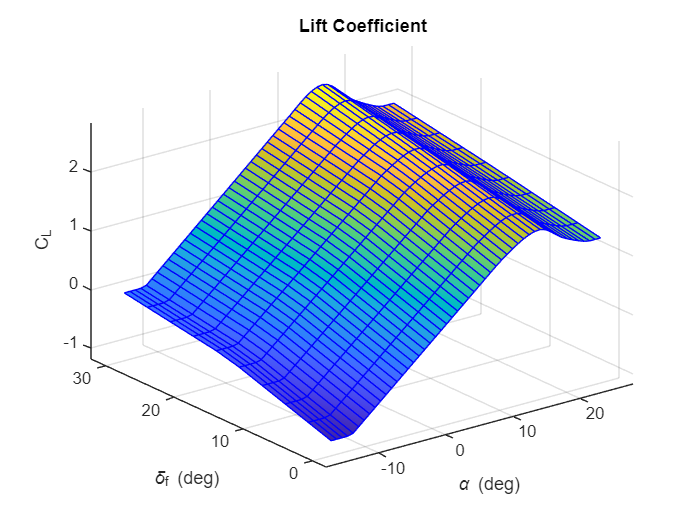

AircraftData.Aerodynamics.Interp.AoA_bp = AircraftData.Aerodynamics.Interp.AoA_Interp_TO;
AircraftData.Aerodynamics.Interp.delta_f_deg_bp = [AircraftData.Aerodynamics.delta_flap_deg_CLEAN, AircraftData.Aerodynamics.delta_flap_deg_TO, AircraftData.Aerodynamics.delta_flap_deg_LND];

AircraftData.Aerodynamics.Interp.CL_Interp = [ ...
    AircraftData.Aerodynamics.Interp.CL_Interp_CLEAN; 
    AircraftData.Aerodynamics.Interp.CL_Interp_TO; ...
    AircraftData.Aerodynamics.Interp.CL_Interp_LND];

% Plot the function: CL(alpha, delta_f)
[m_AoA, m_delta_f_deg] = meshgrid( ...
    AircraftData.Aerodynamics.Interp.AoA_bp, ...
    AircraftData.Aerodynamics.Interp.delta_f_deg_bp);
m_CL = AircraftData.Aerodynamics.Interp.CL_Interp;

vv_AoA = convang(linspace(-15, 25, 50),'deg','rad');
vv_delta_f_deg = linspace(0, 30, 10);
[mm_AoA, mm_delta_f_deg] = meshgrid(vv_AoA, vv_delta_f_deg);
mm_CL = interp2( ...
    m_AoA, m_delta_f_deg, m_CL, ...
    mm_AoA, mm_delta_f_deg, 'bilinear');

s_CL = mesh(convang(mm_AoA,'rad','deg'), mm_delta_f_deg, mm_CL, 'EdgeColor', 'blue');
s_CL.FaceColor = 'interp';
title(['Lift Coefficient'])
xlabel('\alpha (deg)'); ylabel('\delta_f (deg)'); zlabel('C_L') 
axis padded

### Thrust

Thrust is calculated by an interpolant function:


$$T=\frac{T}{T_0 }\left(M,h\right)\cdot T_0$$


#### TAKE-OFF

load 'Data_TP_TO'

AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_TO = Thrust_Ratio_Interp_TO;
AircraftData.Propulsion.Interp.TSFC_Interp_TO         = TSFC_Interp_TO;

% Estimate T_0 
AircraftData.Propulsion.T_0_TO_est = ...
    AircraftData.Propulsion.PI_avail_0/(0.7*V_LO) ... % usual approach: average thrust -> at 70% of V_LO
    *1.2 ...                                          % estimate T0 by scaling the ground-run average thrust
    ;
fprintf("Estimated T_0 at take-off (kN): %s", num2str(AircraftData.Propulsion.T_0_TO_est/1000))

Estimated T_0 at take-off (kN): 99.2508

From the manufacturer

T0 = 2 * 6860 lbf

PI0 = 2 * 2450 hp

% Prepare function evaluating max thrust at take-off in N

% Breakpoints
AircraftData.Propulsion.Interp.v_Mach_Thrust_TO_bp = v_Mach_Thrust_TO_bp; % linspace(0, 0.6, 52);
AircraftData.Propulsion.Interp.v_h_ft_Thrust_TO_bp = v_h_ft_Thrust_TO_bp; % [0 5000 10000 15000]; % altitudes in feet

% interpolating function
AircraftData.Propulsion.Interp.f_Thrust_TP_TO = @(h_m, Mach) ...
    f_ThrustRatio_TP_TO(AircraftData, Mach, convlength(h_m, 'm', 'ft')) ... % 2-D function
    *AircraftData.Propulsion.T_0_TO_est ...
    ;

% Double check T_0 from function call
AircraftData.Propulsion.Thrust_0_TO = AircraftData.Propulsion.Interp.f_Thrust_TP_TO( ...
    convlength(h_0,'m','ft'), ... % convert altitudes in feet
    0.0); % at Mach=0

fprintf("Interpolated T0 at take-off (kN): %s", num2str(AircraftData.Propulsion.Thrust_0_TO/1000))

Interpolated T0 at take-off (kN): 99.2727

fprintf("Max available power at take-off (kW): %s", num2str(AircraftData.Propulsion.PI_avail_0/1000))

Max available power at take-off (kW): 3485

#### CLIMB

load 'Data_TP_CLIMB'

AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_CLIMB = Thrust_Ratio_Interp_CLIMB;
AircraftData.Propulsion.Interp.TSFC_Interp_CLIMB         = TSFC_Interp_CLIMB;

% Breakpoints
AircraftData.Propulsion.Interp.v_Mach_Thrust_CLIMB_bp = v_Mach_Thrust_CLIMB_bp; % linspace(0, 0.6, 52);
AircraftData.Propulsion.Interp.v_h_ft_Thrust_CLIMB_bp = v_h_ft_Thrust_CLIMB_bp; % [0 5000 10000 15000 20000 25000 30000]; % altitudes in feet

% interpolating function
AircraftData.Propulsion.Interp.f_Thrust_TP_CLIMB = @(h_m, Mach) ...
    f_ThrustRatio_TP_CLIMB(AircraftData, Mach, convlength(h_m, 'm', 'ft')) ... % 2-D function
    *AircraftData.Propulsion.T_0_TO_est ...
    ;


#### CRUISE

load 'Data_TP_CRUISE'

% NOTICE: Throttle is an independent variable besides Mach and h_ft

AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_CRUISE = Thrust_Ratio_Interp_CRUISE;
AircraftData.Propulsion.Interp.TSFC_Interp_CRUISE         = TSFC_Interp_CRUISE;

% Breakpoints
AircraftData.Propulsion.Interp.v_Mach_Thrust_CRUISE_bp     = v_Mach_Thrust_CRUISE_bp; % linspace(0, 0.6, 52);
AircraftData.Propulsion.Interp.v_Throttle_Thrust_CRUISE_bp = v_Throttle_Thrust_CRUISE_bp; % [0.2,0.3,0.4,0.75,0.95,1];
AircraftData.Propulsion.Interp.v_h_ft_Thrust_CRUISE_bp     = v_h_ft_Thrust_CRUISE_bp; % [0 5000 10000 15000 20000 25000 30000]; % altitudes in feet


% interpolating function
AircraftData.Propulsion.Interp.f_Thrust_TP_CRUISE = @(h_m, Mach, throttle) ...
    f_ThrustRatio_TP_CRUISE(AircraftData, Mach, convlength(h_m, 'm', 'ft'), throttle) ... % 3-D function
    *AircraftData.Propulsion.T_0_TO_est ...
    ;

### Thrust Specific Fuel Consumption, TSFC - original units: lbf/(lbf*hr) -> SI units: (9.81/3600) * kg/(N*s)

% Use the same break-points that define thrust interpolation 
% v_Mach_Thrust_TO_bp = linspace(0, 0.6, 52);
% v_h_ft_Thrust_TO_bp = [0 5000 10000 15000];

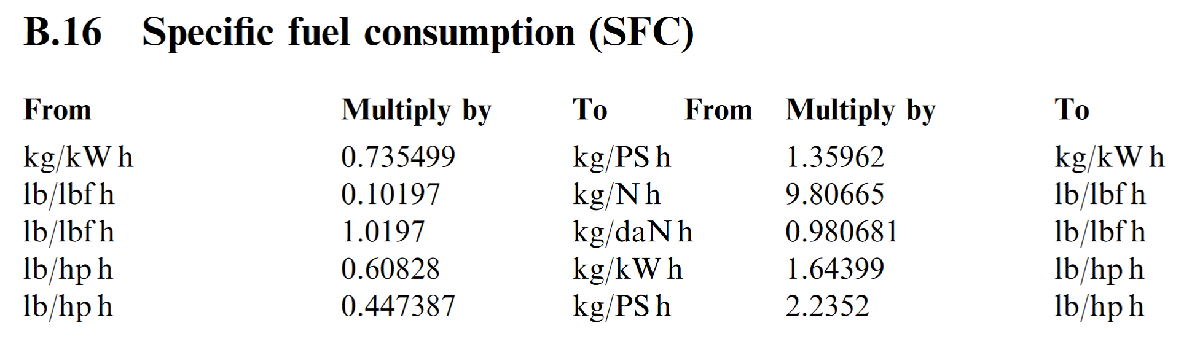

% See table above
% lbm_of_fuel/(hr * lbf_of_thrust) = 1/(9.81*3600) kg/(N*s) = 2.83e-5 kg/(N*s)
AircraftData.Propulsion.tsfc2SI = 2.83e-5;


#### f_TSFC CRUISE

% interpolating function
AircraftData.Propulsion.Interp.f_TSFC_TP_CRUISE = @(h_m, Mach, throttle) ...
    f_TSFC_TP_CRUISE(AircraftData, Mach, convlength(h_m, 'm', 'ft'), throttle) ... % 3-D function
    ;

## Data for 6-DoF and 3-DoF Simulations - TODO

### Weights, balance, and inertias

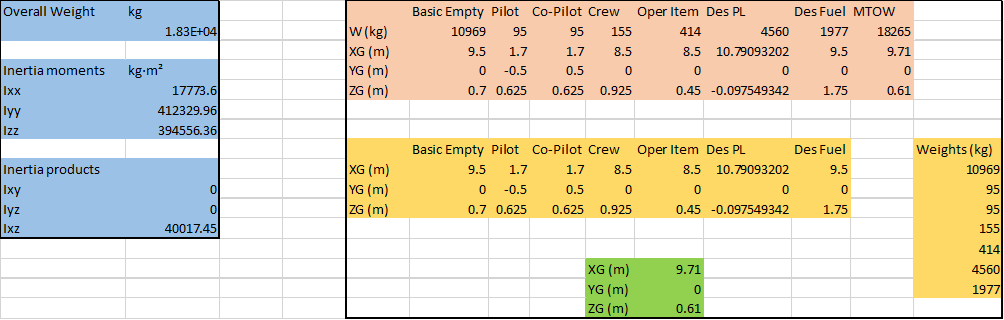

### Save AircraftData

save("AircraftData.mat","AircraftData")